set(0,'defaulttextinterpreter','latex')
rssiData = dlmread('RSSIdata_filtered.txt', '\t'); %#ok<DLMRD>
raw_rssi = zeros(length(rssiData)/2, 1);
filtered_rssi = zeros(length(rssiData)/2, 1);
Ts = 1.0091;
a = 1;
for i = 1:2:length(rssiData)
    raw_rssi(a) = rssiData(i);
    a = a + 1;
end
b = 1;
for j = 2:2:length(rssiData)
    filtered_rssi(b) = rssiData(j);
    b = b + 1;
end
t = 0:Ts:(length(raw_rssi) - 1) * Ts; % Adjusted t vector

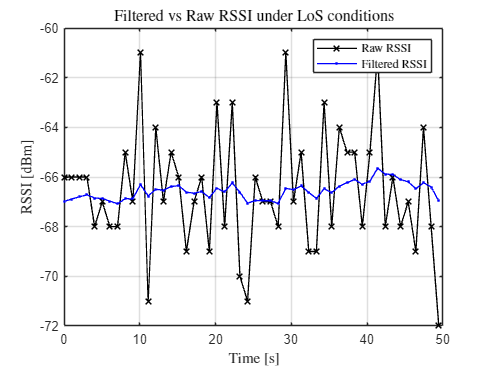

plot(t,raw_rssi,"-x",'LineWidth',1,'color', 'k');
xlabel("Time [s]");
ylabel("RSSI [dBm]");
title("Filtered vs Raw RSSI under LoS conditions",'FontSize',12)
hold on
plot(t,filtered_rssi, '.-','LineWidth',1,'Color','b')
legend('Raw RSSI', 'Filtered RSSI', 'Interpreter', 'latex');
grid on
print -depsc rssiMovingAverage

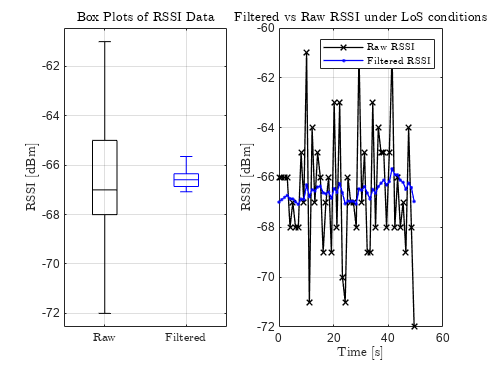

figure;
t = 0:Ts:(length(raw_rssi) - 1) * Ts;

% Creating subplots, the first for box plots, the second for time series plot
subplot(1,2,1);
boxplot([raw_rssi, filtered_rssi], 'Colors', ['k', 'b'], 'Labels', {'Raw', 'Filtered'});
bp = gca;
bp.XAxis.TickLabelInterpreter = 'latex';
h=findobj('LineStyle','--'); set(h, 'LineStyle','-');
ylabel('RSSI [dBm]');
title('Box Plots of RSSI Data');
grid on

subplot(1,2,2);
plot(t, raw_rssi, '-x', 'LineWidth', 1, 'Color', 'k');
hold on;
plot(t, filtered_rssi, '.-', 'LineWidth', 1, 'Color', 'b');
xlabel('Time [s]');
ylabel('RSSI [dBm]');
title('Filtered vs Raw RSSI under LoS conditions');
legend('Raw RSSI', 'Filtered RSSI', 'Interpreter', 'latex');
grid on;

fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 8]; % This will stretch the plot across an 11x8.5 inch page
fig.PaperSize = [20 8];

% Use the following command to save the figure in MATLAB
print(fig, 'rssiMovingAverage','-depsc','-r600');

filtered_avg = mean(filtered_rssi)

filtered_avg = -66.5635

raw_avg = mean(raw_rssi)

raw_avg = -66.5400

filtered_std = std(filtered_rssi)

filtered_std = 0.3398

raw_std = std(raw_rssi)

raw_std = 2.4761

filtered_range = max(filtered_rssi) - min(filtered_rssi)

filtered_range = 1.4293

raw_range = max(raw_rssi) - min(raw_rssi)

raw_range = 11

max_raw = max(raw_rssi)

max_raw = -61

min_raw = min(raw_rssi)

min_raw = -72

max_filt = max(filtered_rssi)

max_filt = -65.6490

min_filt = min(filtered_rssi)

min_filt = -67.0784

Q_raw = quantile(raw_rssi,[0.25 0.5 0.75 0.9])

Q_raw =    -68   -67   -65   -63


Q_filt = quantile(filtered_rssi,[0.25 0.5 0.75 0.9])

Q_filt =   -66.8622  -66.5934  -66.3475  -66.1359


iqr_raw = iqr(raw_rssi)

iqr_raw = 3

iqr_filt = iqr(filtered_rssi)

iqr_filt = 0.5147